# Inside the black box

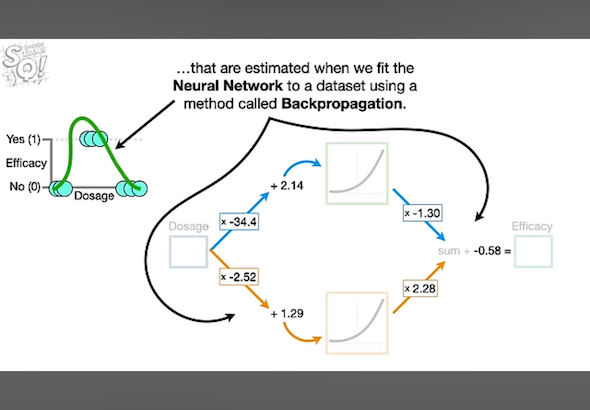

dosage = 0.5;
w = zeros(4,1);
w(1) = 3.34;
w(2) = -3.53;
w(3:4,:) = [0.36 0.63];
b = zeros(3,1);
b(1) = -1.43;
b(2) =  0.57;
b(3) =  0;
observed = [0 1 0];
learningRate = 0.1;
bStep = zeros(3,1);
wStep = zeros(4,1);
stepSize = 10;
howMany = 0;
while abs(stepSize) > 0.005
    [predicted, L1] = getEff(0:0.5:1,w,b);
    SSR_prime_b3 = sum(-2 .* (observed - predicted));
    w34Deriv= -2 .* (observed - predicted) .* L1;
    wStep(3:4,:) = sum(learningRate * w34Deriv ,2);
    bStep(3) = learningRate * SSR_prime_b3;
    stepSize = max(abs(bStep));
    b = b - bStep;
    w(3:4) = w(3:4) - wStep(3:4);
    howMany = howMany+1;
end
howMany

howMany = 166

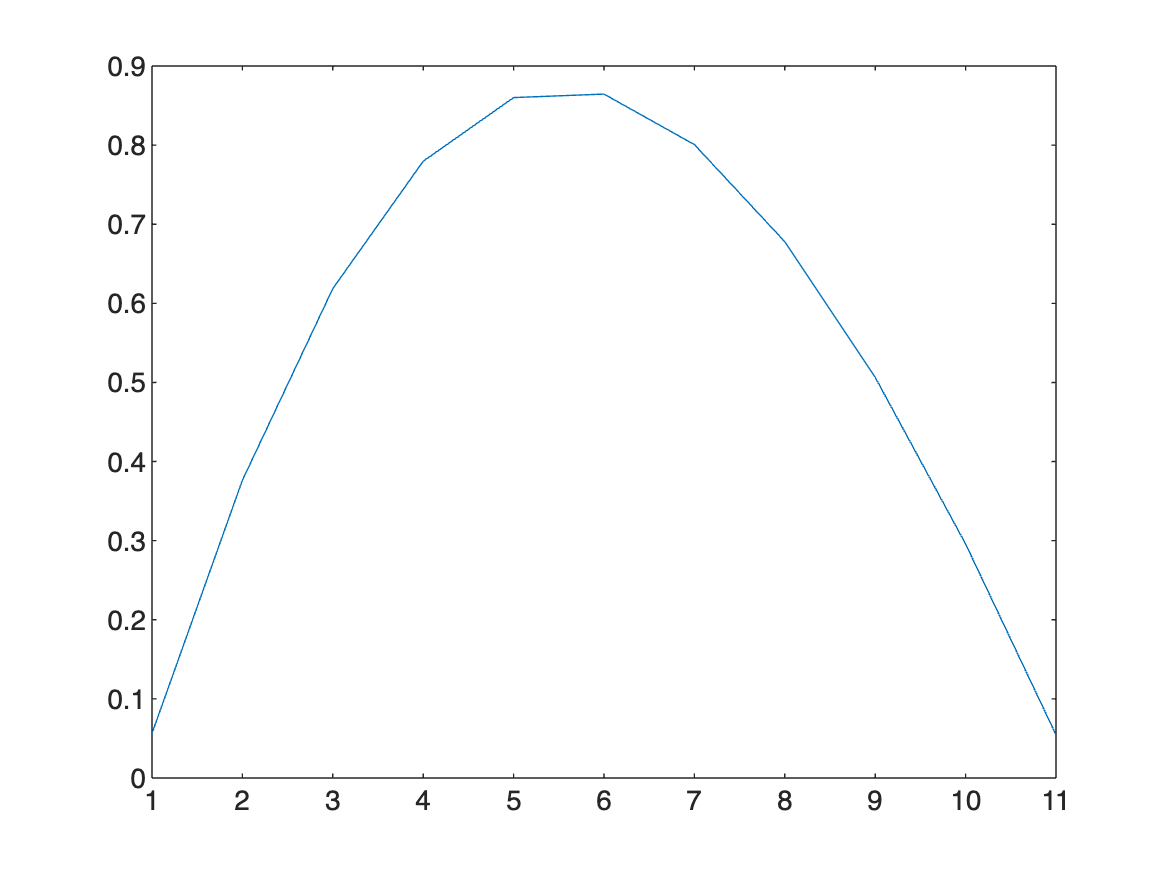

effGraph = getEff(0:0.1:1,w,b);
plot(effGraph)


function [efficacy, L1] = getEff(dosage, w, b)
    xs = dosage .* w(1:2,:) + b(1:2,1);
    L1 = softplus(xs);
    blueOrange = L1 .* w(3:4,:);
    greenSquiggle = sum(blueOrange);
    efficacy = greenSquiggle + b(3);
end



## Activation Function

function act = softplus(xx)
    act = log(1+exp(xx));
end
